Import data table and convert to array

load datatable.mat
data = table2array(datatable)

data = 	1.0e+03 *

    0.0010    0.1200    0.3000    0.0020    0.1180    0.7961
    0.0010    0.1200    0.3000    0.0035    0.1180    1.4769
    0.0010    0.1200    0.3000    0.0050    0.1180    1.7975
    0.0010    0.1200    0.4000    0.0020    0.1204    0.8060
    0.0010    0.1200    0.4000    0.0035    0.1204    1.4875
    0.0010    0.1200    0.4000    0.0050    0.1205    1.8221
    0.0010    0.1200    0.5000    0.0020    0.1221    0.8606
    0.0010    0.1200    0.5000    0.0035    0.1221    1.4049
    0.0010    0.1200    0.5000    0.0050    0.1221    1.9555
    0.0010    0.1400    0.3000    0.0020    0.1398    0.8128


p = data(:,1:4)';
t = data(:,5:6)';

p1 = p(1,:);
p2 = p(2,:);
p3 = p(3,:);
p4 = p(4,:);

t1 = t(1,:);
t2 = t(2,:);

p1n = (data(:,1)-min(data(:,1)))./(max(data(:,1))-min(data(:,1)));
p2n = (data(:,2)-min(data(:,2)))./(max(data(:,2))-min(data(:,2)));
p3n = (data(:,3)-min(data(:,3)))./(max(data(:,3))-min(data(:,3)));
p4n = (data(:,4)-min(data(:,4)))./(max(data(:,4))-min(data(:,4)));
t1n = (data(:,5)-min(data(:,5)))./(max(data(:,5))-min(data(:,5)));
t2n = (data(:,6)-min(data(:,6)))./(max(data(:,6))-min(data(:,6)));

pn = [p1n p2n p3n p4n]';
tn = [t1n t2n]';

for n=1:50                    %number of neuron
net0 = fitnet(n,'trainlm');              %fitnet(hiddenlayersize,training function)
net0.divideParam.trainRatio  = 0.8;
net0.divideParam.valRatio    = 0.2;
net0.divideParam.testRatio   = 0;
net0.trainParam.epochs       = 100;      %Maximum number of epochs to train. The default value is 1000.
net0.trainParam.goal         = 0;        %Performance goal. The default value is 0
net0.trainParam.max_fail     = 10;       %Maximum validation failures. The default value is 6.
net0.trainParam.min_grad     = 1e-06;    %Minimum performance gradient. The default value is 1e-5.
net0.trainParam.show         = 100       %Epochs between displays (NaN for no displays). The default value is 25.
net0.trainParam.showWindow   = true;     %Show training GUI. The default value is true.
net0.trainParam.time         = inf;      %Maximum time to train in seconds. The default value is inf.
net0.performFcn              = 'mse';    %There are mae mse sae sse available in MATLAB
net0.inputs{1}.processFcns   = {'removeconstantrows'};
net0.outputs{2}.processFcns  = {'removeconstantrows'};
net0.layers{1}.transferFcn = 'tansig';

[net0,tr0] = train(net0,pn,tn);
mse_val0(n)= tr0.best_vperf;
[M0,I0] = min(mse_val0);        % update the latest minimum mse value (M0) with its index (I0)
end

net0 =

    Neural Network
 
              name: 'Function Fitting Neural Network'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 1
         numLayers: 2
        numOutputs: 1
    numInputDelays: 0
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 1
        sampleTime: 1
 
    connections:
 
       biasConnect: [1; 1]
      input


plot(mse_val0,'-');

disp('training index of best MSE value set is')

training index of best MSE value set is


disp(I0)

    32



disp('Which has MSE =')

Which has MSE =


disp(M0)

    8.1557



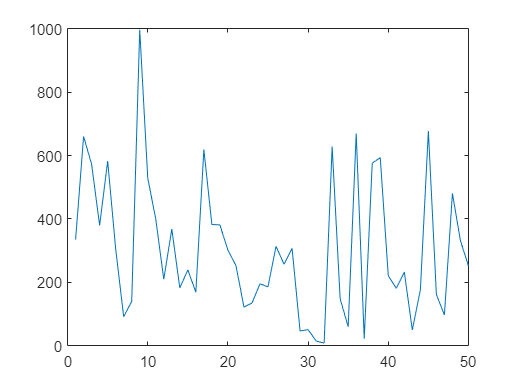

hold off;

net1 = fitnet(9,'trainlm');              %fitnet(hiddenlayersize,training function)
net1.divideParam.trainRatio  = 0.8;
net1.divideParam.valRatio    = 0.2;
net1.divideParam.testRatio   = 0;
net1.trainParam.epochs       = 100;      %Maximum number of epochs to train. The default value is 1000.
net1.trainParam.goal         = 0;        %Performance goal. The default value is 0.
net1.trainParam.lr           = 0.01;     %Learning rate. The default value is 0.01.
net1.trainParam.max_fail     = 10;       %Maximum validation failures. The default value is 6.
net1.trainParam.min_grad     = 1e-06;    %Minimum performance gradient. The default value is 1e-5.
net1.trainParam.show         = 100       %Epochs between displays (NaN for no displays). The default value is 25.

net1 =

    Neural Network
 
              name: 'Function Fitting Neural Network'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 1
         numLayers: 2
        numOutputs: 1
    numInputDelays: 0
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 9
        sampleTime: 1
 
    connections:
 
       biasConnect: [1; 1]
      input

net1.trainParam.showWindow   = true;     %Show training GUI. The default value is true.
net1.trainParam.time         = inf;      %Maximum time to train in seconds. The default value is inf.
net1.performFcn              = 'mse';    %There are mae mse sae sse available in MATLAB
net1.inputs{1}.processFcns   = {'removeconstantrows'};
net1.outputs{2}.processFcns  = {'removeconstantrows'};
net1.layers{1}.transferFcn = 'tansig';

[net1,tr1] = train(net1,pn,tn);
output_ANN1 = net1(pn)

output_ANN1 =     0.4998    0.4989    0.4957    0.5237    0.5255    0.5200    0.5482    0.5507    0.5441    0.7065    0.7048    0.7058    0.7297    0.7331    0.7304    0.7515    0.7566    0.7524    0.9233    0.9233    0.9291    0.9449    0.9475    0.9503    0.9200    0.9244    0.9237    0.9924    0.9892    0.9924    0.2168    0.2165    0.2138    0.1512    0.1532    0.1474    0.3664    0.3612    0.3658    0.2932    0.2923    0.2927    0.3059    0.3087    0.3052    0.4189    0.4149    0.4215    0.4288    0.4264
    0.0441    0.5210    0.6933    0.0577    0.4627    0.7722    0.1000    0.5000    0.8517    0.0893    0.6427    0.6210    0.0324    0.4772    0.6626    0.0975    0.4828    0.7764    0.0333    0.7375    0.5517    0.0061    0.4706    0.5541    0.1609    0.4232    0.6669    0.0666    0.6850    0.6170    0.1170    0.5701    0.7223    0.1285    0.4944    0.7561    0.0608    0.7695    0.5219    0.0835    0.6430    0.6081    0.1353    0.5214    0.6815    0.0390    0.7690    0.4443    0

ANNIPF = ((output_ANN1(1,:))*(max(data(:,5))-min(data(:,5))))+min(data(:,5))

ANNIPF =   117.5153  117.4209  117.0858  120.0163  120.1960  119.6282  122.5705  122.8361  122.1507  139.1374  138.9576  139.0615  141.5653  141.9171  141.6309  143.8470  144.3819  143.9386  161.8152  161.8183  162.4231  164.0713  164.3468  164.6418  161.4662  161.9302  161.8600  169.0492  168.7143  169.0399   87.9099   87.8809   87.5906   81.0405   81.2494   80.6433  103.5591  103.0139  103.4957   95.8964   95.8068   95.8437   97.2238   97.5164   97.1520  109.0484  108.6272  109.3256  110.0805  109.8340


ANNSEA = ((output_ANN1(2,:))*(max(data(:,6))-min(data(:,6))))+min(data(:,6))

ANNSEA = 	1.0e+03 *

    0.7952    1.5045    1.7608    0.8154    1.4178    1.8782    0.8783    1.4734    1.9965    0.8625    1.6856    1.6532    0.7778    1.4394    1.7152    0.8746    1.4477    1.8844    0.7791    1.8266    1.5503    0.7386    1.4296    1.5538    0.9689    1.3591    1.7215    0.8286    1.7485    1.6473    0.9037    1.5776    1.8040    0.9208    1.4650    1.8543    0.8200    1.8742    1.5059    0.8538    1.6861    1.6342    0.9308    1.5052    1.7432    0.7876    1.8735    1.3905    0.7748    1.6845


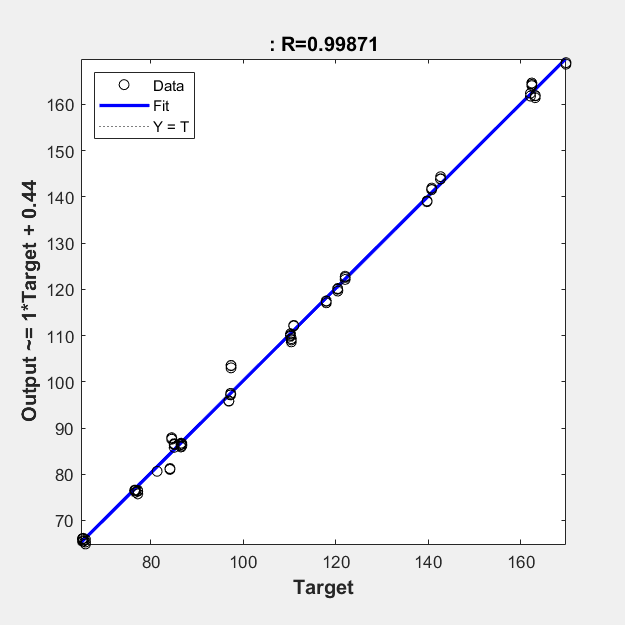

plotregression(t1,ANNIPF)

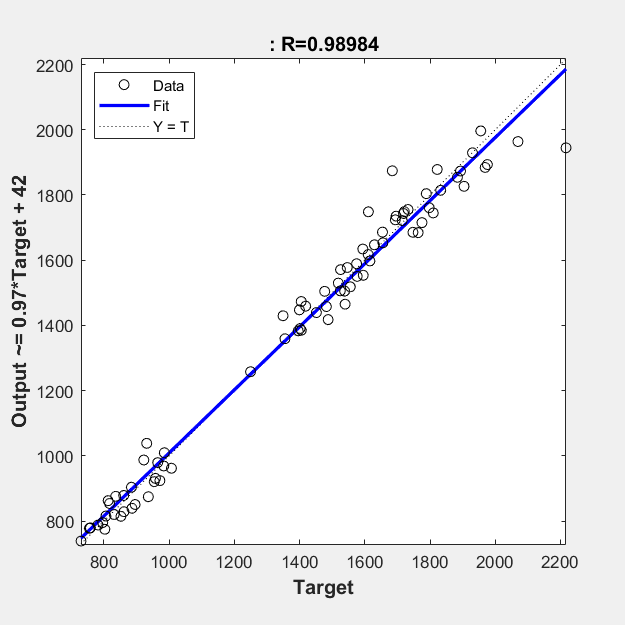

plotregression(t2,ANNSEA)

pred = net1([0.75 0.75 0.75 0.75]')

pred =     0.7033
    0.4865



IPF = ((pred(1,:))*(max(data(:,5))-min(data(:,5))))+min(data(:,5))

IPF = 138.7970

SEA = ((pred(2,:))*(max(data(:,6))-min(data(:,6))))+min(data(:,6))

SEA = 1.4532e+03